# Estimation, Filtering and Detection

## Homework 3B: Current Sensor Fault

## Timur Uzakov

## MACROS

clear all;
storeFigures = false; % set true if you want to save plots

## Problem 1:

% Design healthy (m=1) state-space model
% Design faulty  (m=2) state-space model
% Find controller gain K_p to keep current limited to 200 A and no
% overshoot
% Analyze observability of m1
% Analyze observability of m2

% Motor parameters
R = 0.1;                % Ohms
L = 0.5;                % Henrys
Kt = 0.5;               % torque constant
Km = 0.5;               % motor constant
Bm = 0.0011;            % Nms/rad viscous friction
J = 10;                 % kg.m^2/s^2

% Healthy system m=1

A = [-Bm/J Kt/J; -Km/L -R/L];
B = [0 0; 1/L -1/L];
C = [1 0;0 1];
D = 0;
sys_healthy = ss(A,B,C,D);

% Faulty system m=2

A_f = [-Bm/J Kt/J; -Km/L -R/L];
B_f = [0 0; 1/L -1/L];
C_f = [1 0;0 0];
D_f = 0;
sys_faulty = ss(A_f,B_f,C_f,D_f);

% Observability
disp("Observability of healthy system")

Observability of healthy system


Ob_healthy = obsv(A,C);
unobsv = length(A) - rank(Ob_healthy)

unobsv = 0

disp("Observability of faulty system")

Observability of faulty system


Ob_faulty = obsv(A_f,C_f);
unobsv = length(A_f) - rank(Ob_faulty)

unobsv = 0

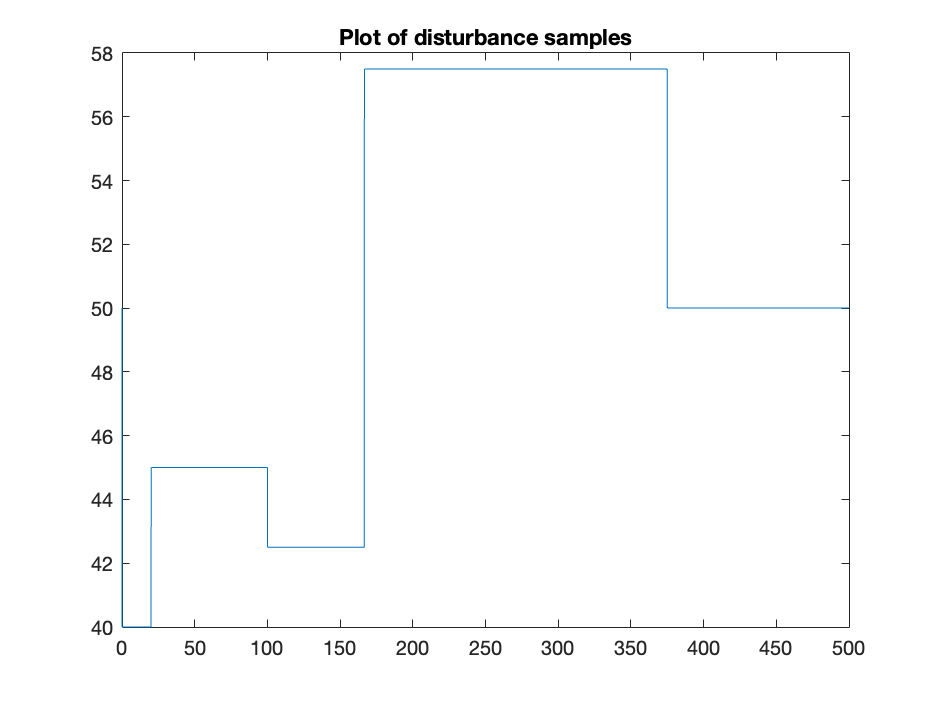




% disturbance
Ts = 0.05;
N = 10000;
T = Ts*N;
t = 0:Ts:T;
load = 50;        % Nm
deviation = 10;
Td = load*ones(1,N); % load disturbance
for i=1:N
    if i<=N/25
        Td(i) = Td(i) - deviation;
    end
    if i>N/25 && i<=N/5
        Td(i) = Td(i) - deviation/2;
    end
    if i>N/5 && i<=N/3
        Td(i) = Td(i) - 3*deviation/4;
    end
    if i>N/3 && i<=3*N/4
        Td(i) = Td(i) + 3*deviation/4;
    end
end
Td = [load Td];
figure;
plot(t,Td);
title("Plot of disturbance samples");

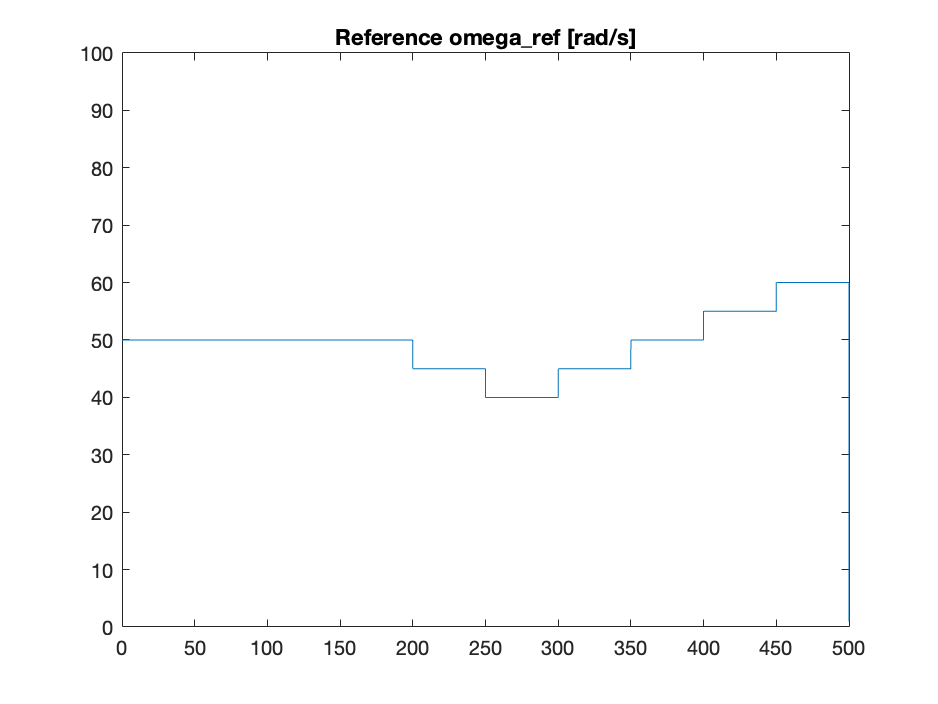


% refference signal
w_ref = ones(size(t));
for i=1:N
    if i<=N/10
        w_ref(i) = 50;
    end
    if i>N/10 && i<=2*N/10
        w_ref(i) = 50;
    end
    if i>2*N/10 && i<=3*N/10
        w_ref(i) = 50;
    end
    if i>3*N/10 && i<=4*N/10
        w_ref(i) = 50;
    end
    if i>4*N/10 && i<=5*N/10
        w_ref(i) = 45;
    end
    if i>5*N/10 && i<=6*N/10
        w_ref(i) = 40;
    end
    if i>6*N/10 && i<=7*N/10
        w_ref(i) = 45;
    end
    if i>7*N/10 && i<=8*N/10
        w_ref(i) = 50;
    end
    if i>8*N/10 && i<=9*N/10
        w_ref(i) = 55;
    end
    if i>9*N/10 && i<=N
        w_ref(i) = 60;
    end
end
figure();
plot(t,w_ref);
ylim([0 100]);
title("Reference omega\_ref [rad/s]");



u = [50*ones(1,length(Td));zeros(1,length(Td))];
% Kp = 1; % 0.01
Ki = 0.075;
Kp = 0.25;
Kd = 1.5;
% C_contr = tf(Kp);                 % P controller
% C_contr = tf([Kp Ki],[1 0])      % PI controller
C_contr = tf([Kd Kp Ki],[1 0])      % PID controller

C_contr =
 
  1.5 s^2 + 0.25 s + 0.075
  ------------------------
             s
 
Continuous-time transfer function.



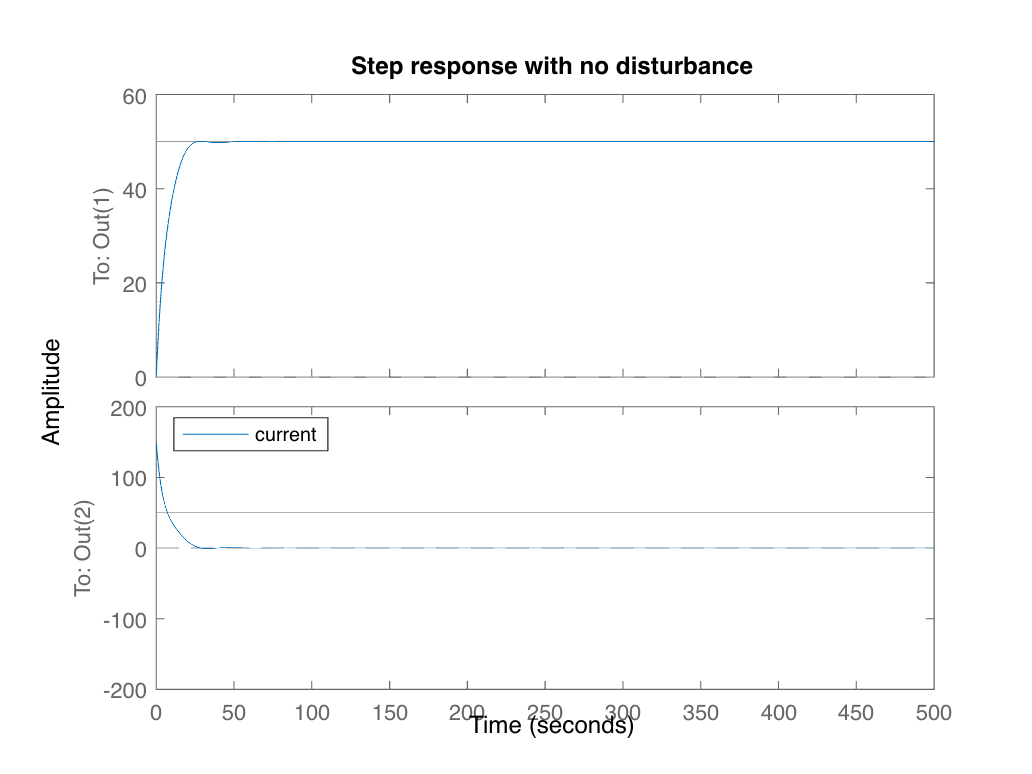

% C_contr = tf(Ki,[1 0]);           % compensator K/s

cl = feedback(sys_healthy * append(C_contr,1),1,1,1);
h = lsimplot(cl,u,t);
cl_rloc.InputName = {'w_ref','Td'};
cl_rloc.OutputName = 'w';
title('Step response with no disturbance')
legend('current','Location','NorthWest')
ylim([-200 200])

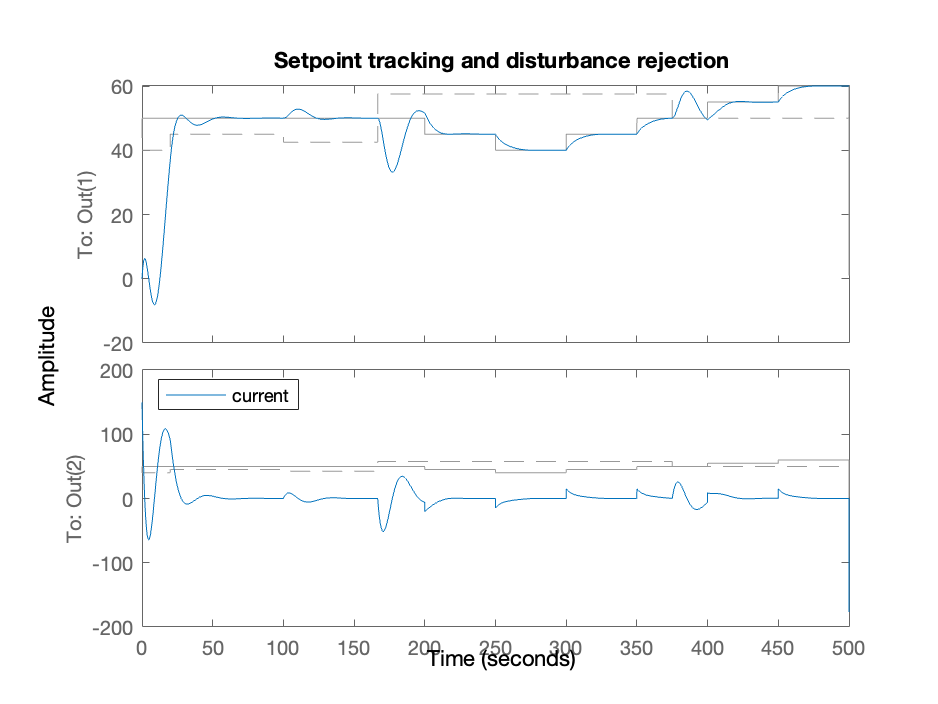


u = [w_ref ; Td];       % w_ref=1 and Td
cl = feedback(sys_healthy * append(C_contr,1),1,1,1);
h = lsimplot(cl,u,t);
cl_rloc.InputName = {'w_ref','Td'};
cl_rloc.OutputName = 'w';
title('Setpoint tracking and disturbance rejection')
legend('current','Location','NorthWest')
ylim([-200 200])

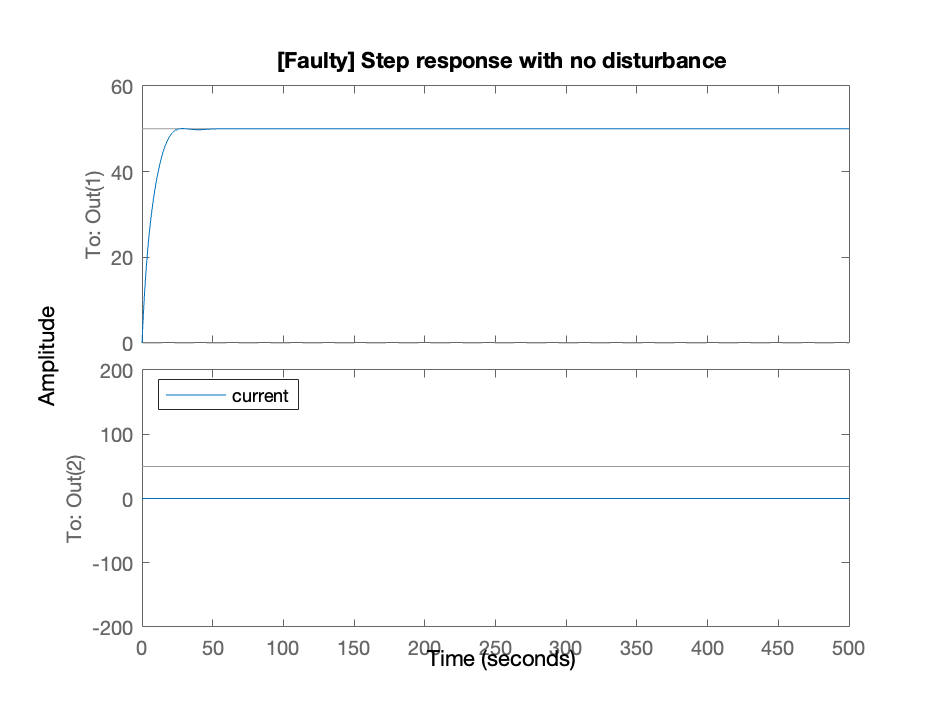


u = [50*ones(1,length(Td));zeros(1,length(Td))];
cl = feedback(sys_faulty * append(C_contr,1),1,1,1);
h = lsimplot(cl,u,t);
cl_rloc.InputName = {'w_ref','Td'};
cl_rloc.OutputName = 'w';
title('[Faulty] Step response with no disturbance')
legend('current','Location','NorthWest')
ylim([-200 200])

## Problem 2:

% Select and justify process noise properties
% Find input-output data with multiple sensor faults

## Problem 3:

%% Conclusion: the longer the Tc, the worse is prediction covariance

## Problem 4:

## Problem 5:

## Additional tools

% Storing figures
if storeFigures
    for i=1:10
        filename = strcat('figure_',num2str(i));
        foldername = './figures/';
        saveas(figure(i),fullfile(foldername,filename),'jpg');
    end
end